# PowderTAS

The "powderTAS" Matlab code calculates neutron scattering cross-sections of powder samples, represented as Q-E scattering maps, using "single-crystal" phonon calculation eigenvectors as input. The name comes from the original not-to-be-repeated neutron experiment where we put a powder sample on a three-axis spectrometer (TAS). The whole concept of this code is to do a powder average over a high-number of Q-points, randomly generated at a distance |Q| (controlled by the variable command.Q) from the origin, forming a sphere (the positive quadrant of it). At each point on this sphere, the eigenvectors are obtained by trilinear interpolation, and using them, the scattering cross-sections (elastic and inelatic, coherent and incoherent) are calculated. These cross-sections are then used to make an histrogram-spectra, which can be seen as a line in a frequency/momentum map. This process is repeated for all Q-values set by the variable command.Q, hence forming the complete scattering map of a powder sample.

Concerning the script itself, the number of Q-vectors per shell is defined with the variable (command.Nvec). Depending on the size (command.Q) and resolution of the scattering map (command.resolution_map_q, command.resolution_map_w), one may need to use a tremendous amount of Q-points. In that case some memory issues may arise, which are address by using a repetition scheme: the calculation on a reasonable number of q-points (command.Nvec * length(command.Q)), is reproduced command.Nrep times. At every iteration the calculated scattering function is added to the maps. structure, but only the scattering function of the last iteration is stored in the lastrep structure. The plot of the scattering maps is updated after each repetition. To get a decent enough statistics, I would recommend to use at least command.Nvec=1e5, which for a single Q-point takes about 150 seconds. For a full map with high resolution, command.Q=(0:0.01:5), this statistics may be reached for instance with Nrep=20 and Nvec=5000, which takes approximately 20 hours. Some form of convolution to the experimental resolution of an instrument can be performed, but for now only for the energy dimension, and only for a simplistic model of a gaussian-shaped energy resolution with a width defined by (flat+scaling).

See each function header for more info.

## Initialisation

clear; close all; clc;
addpath functions;

## Loader

Data files are to be put in the "dat/" folder. Cell parameter (cubic only so far), list of atoms, and atomic positions should be provided as follow:

data.filename='mesh_50x50x50_reducible_PBE'; data.latval=4.237; data.sortatom={'O','O','O','Ba','Zr'}; data.position=[.75,.75,.25;.25,.75,.75;.75,.25,.75;.25,.25,.25;.75,.75,.75];

## Control parameters

For a single Q-point, for instance at hkl = (1.5 1.5 1.5),

- set "command.Q=2*pi*sqrt((**1.5**)^2+(**1.5**)^2+(**1.5**)^2)/data.latval;"

- set "command.Nrep=1;"

- set "command.Nvec=100000;"

For the full map, up to 5 [AA-1] with a good resolution,

- set "command.Q=(0:0.01:5);"

- set "command.Nrep=20;"

- set "command.Nvec=5000;"

The variable "command.dQ" represents the spread in Q of each Q-sphere, [Q-dQ/2:Q+dQ/2]. The purpose is to probe the entire Q-space, and not just a mesh. The value of dQ should be set accordingly to the step of "command.Q". For instance, for "command.Q=(0:**0.01**:5)", set "command.dQ=**0.01**;". For a single Q-point it doesn't really matter, but it can be used to match the instrument resolution. For instance, on the IN8 three-axis spectrometer, the Q-resolution is 0.03, hence one could choose "command.dQ=0.03";.

The variable "command.temperature" is to set the temperature of the system, which affects the Bose population and the Debye-Waller factor, and hence the scattering cross-sections.

command.Nrep=1;                                 % Number of repetitions to build statistics
command.Nvec=100000;       	                % Number of Q-vectors used for powder average
command.Q=2*pi*sqrt(3*(1.5)^2)/data.latval;     % Q-point for the omega scan [AA-1]
% command.Q=(0:0.01:5);      	                % Q-mesh for 2D omega/Q maps [AA-1]
command.dQ=0.01;           	                % Spread in Q of the selected Q-point [AA-1]
command.temperature=5;     	                % Temperature [K]

## Instrument and figure resolution

Resolution of the scattering map in Q and energy. Default values would be "command.resolution_map_w=0.1;" and "command.resolution_map_q=0.01;".

command.resolution_map_w=0.1;          	        % scattering map E resolution [meV]
command.resolution_map_q=0.01;         	        % scattering map Q resolution [AA-1]

Resolution of the instrument. For instance, "command.resolution_instr_w=[0.57,0.02];" is to be read as "an energy resolution of 0.57 meV at the elastic line, that increases with energy transfer at a rate of 2% of the energy transfer".

command.resolution_instr_w=[0.57,0.02];	        % instrumental E resolution (IN8) [flat(meV),scaling(%)]
command.resolution_instr_q=[0.03,0];  	        % instrumental Q resolution (IN8) [flat(AA-1),scaling(%)]

## Import data

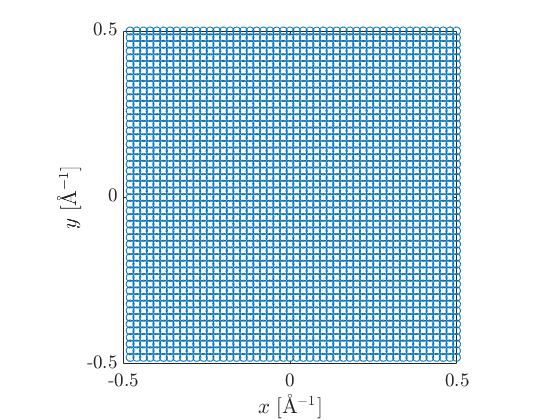

data=import_mesh_HDF5(data);

## Get cross-sections and masses sorted

data=powdertas_library(data);

## Allocate scattering maps

maps.w=(0:command.resolution_map_w:120)'; maps.q=command.Q';
maps.sqw_coh=zeros(length(maps.w),length(maps.q));
maps.sqw_inc=zeros(length(maps.w),length(maps.q));
maps.sq_inc =zeros(length(maps.w),length(maps.q));
maps.sq_coh =zeros(length(maps.w),length(maps.q));

Repetition 1; 11h34


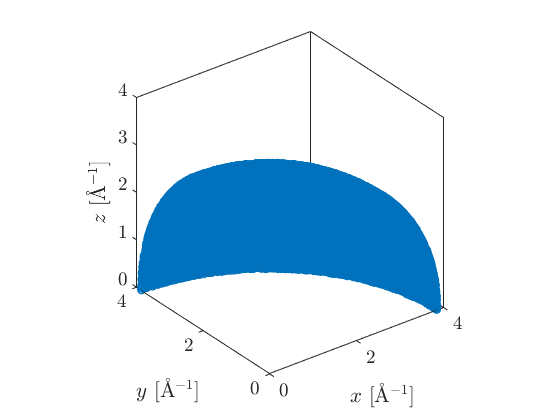

Elapsed time is 142.726132 seconds.


Elapsed time is 10.151644 seconds.


Elapsed time is 9.250032 seconds.


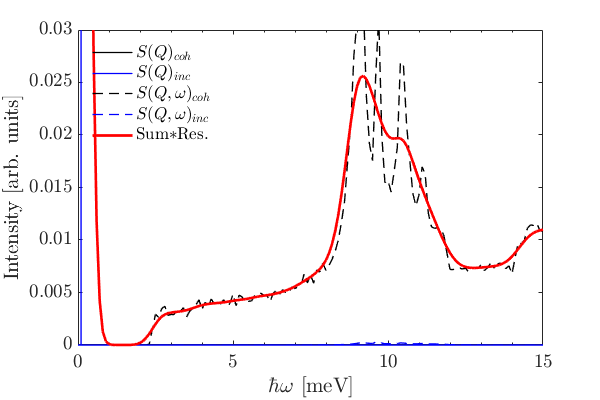

for rep=1:command.Nrep
    % Timestamp
    time=clock; fprintf('Repetition %.0f; %.0fh%.0f\n',rep,time(4),time(5));
    
    % Generate Q-vectors for powder average
    lastrep=powdertas_generate_Q(command);
    
    % Get eigenvectors for each generated Q-vectors by linear interpolation
    tic; lastrep=powdertas_interpolate_eigenvectors(command,data,lastrep); toc;
    
    % Calculate scattering functions
    tic; lastrep=powdertas_scattering_functions(command,data,lastrep); toc;
    
    % Build scattering maps
    tic; maps=powdertas_scattering_maps(command,maps,lastrep); toc;
    
    % Plot (updating)
    powdertas_plotnow(command,maps);
end; clear time rep;

## Save data

Best not to store the "data" and "lastrep" structures, as it takes a tremendous amount of space.

% save('data_R_PBE.mat','maps','-v7.3');
% save('data_0to5_PBE.mat','maps','-v7.3');